# CEE 154/254 - Data Analytics for Physical Systems

## Assignment 4

% Written by Yiwen Dong (ywdong@stanford.edu), Jingxiao Liu (liujx@stanford.edu)
% updated 10/26/2023

## Part I

close all
clear
clc

load hw4_1.mat
pm2d5= data.pm2d5;
time = data.time;
warning ('off','all');

### (a) - (c) Code

time_num = (datenum(time)-floor(datenum(time)))*24*60*60;
train_val_idx = find(time_num<22*60*60); % select the idx of the data from 0:00am – 9:59pm
test_idx = find(time_num>=22*60*60); % select the idx of the data from 10:00pm – 11:59pm

disp(['Data type of time: ', class(time)]);

Data type of time: datetime


disp(['Data type of pm2d5: ', class(pm2d5)]);

Data type of pm2d5: double


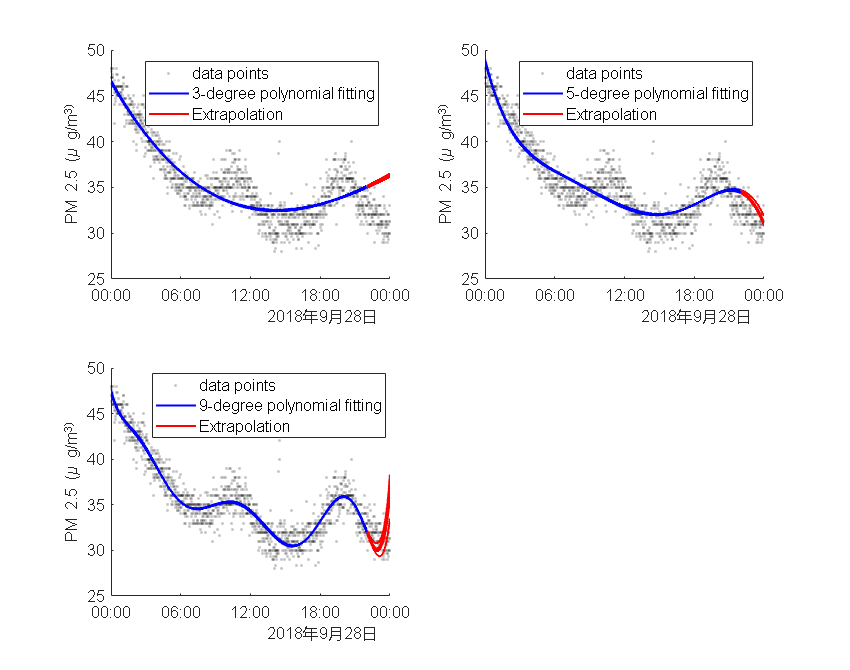


fig = figure('Position', [0,0,850,670]);

subplot(2,2,1)
h = scatter(time,pm2d5,'.k');
h.MarkerFaceAlpha = .25;
h.MarkerEdgeAlpha = .25;
hold on
%%% insert your code here %%%
% note: this is the subplot for (a) and (b), you will need to implement the 5-fold cross validation here
% note: please plot the curves both train and test (extrapolation) data
% hint: MATLAB functions randi(), fix(), polyfit(), polyval() might be helpful

% 5-fold cross-validation for 3-degree polynomial

k = 5; % Number of folds for cross-validation
n = length(train_val_idx); % Number of data points in the training set
indices = crossvalind('Kfold', n, k); % Generate indices for k-fold cross-validation

for i = 1:k
    test = (indices == i); train = ~test;
    train_idx_fold = train_val_idx(train); % Training data indices for the fold
    test_idx_fold = test_idx; % Test data indices are the same for all folds

    % Polynomial fitting for degree 3
    p = polyfit(time_num(train_idx_fold), pm2d5(train_idx_fold), 3);

    % Get fitted values for training and test data
    pm2d5_fit_train = polyval(p, time_num(train_idx_fold));
    pm2d5_fit_test = polyval(p, time_num(test_idx_fold));

    % Plotting training data fit
    plot(time(train_idx_fold), pm2d5_fit_train, 'b', 'LineWidth', 1.5); 

    % Extrapolation for test data
    plot(time(test_idx_fold), pm2d5_fit_test, 'r', 'LineWidth', 1.5); 
end






%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
legend('data points','3-degree polynomial fitting','Extrapolation')
ylabel('PM 2.5 (\mu g/m^3)')
set(findall(gcf,'-property','FontSize'),'FontSize',12)


subplot(2,2,2)
h = scatter(time,pm2d5,'.k');
h.MarkerFaceAlpha = .25;
h.MarkerEdgeAlpha = .25;
hold on
%%% insert your code here %%%
% note: this is the subplot for (c) (i), you will need to implement the 5-fold cross validation here
% hint: MATLAB functions randi(), fix(), polyfit(), polyval() might be helpful

% 5-degree polynomial
for i = 1:k
    test = (indices == i); train = ~test;
    train_idx_fold = train_val_idx(train); % Training data indices for the fold
    test_idx_fold = test_idx; % Test data indices are the same for all folds

    % Polynomial fitting for degree 5
    p = polyfit(time_num(train_idx_fold), pm2d5(train_idx_fold), 5);

    % Get fitted values for training and test data
    pm2d5_fit_train = polyval(p, time_num(train_idx_fold));
    pm2d5_fit_test = polyval(p, time_num(test_idx_fold));

    % Plotting training data fit
    plot(time(train_idx_fold), pm2d5_fit_train, 'b', 'LineWidth', 1.5); 

    % Extrapolation for test data
    plot(time(test_idx_fold), pm2d5_fit_test, 'r', 'LineWidth', 1.5); 
end



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
legend('data points','5-degree polynomial fitting','Extrapolation')
ylabel('PM 2.5 (\mu g/m^3)')
set(findall(gcf,'-property','FontSize'),'FontSize',12)


subplot(2,2,3)
h = scatter(time,pm2d5,'.k');
h.MarkerFaceAlpha = .25;
h.MarkerEdgeAlpha = .25;
hold on
%%% insert your code here %%%
% note: this is the subplot for (c) (ii), you will need to implement the 5-fold cross validation here
% hint: MATLAB functions randi(), fix(), polyfit(), polyval() might be helpful

% 9-degree polynomial
for i = 1:k
    test = (indices == i); train = ~test;
    train_idx_fold = train_val_idx(train); % Training data indices for the fold
    test_idx_fold = test_idx; % Test data indices are the same for all folds

    % Polynomial fitting for degree 9
    p = polyfit(time_num(train_idx_fold), pm2d5(train_idx_fold), 9);

    % Get fitted values for training and test data
    pm2d5_fit_train = polyval(p, time_num(train_idx_fold));
    pm2d5_fit_test = polyval(p, time_num(test_idx_fold));

    % Plotting training data fit
    plot(time(train_idx_fold), pm2d5_fit_train, 'b', 'LineWidth', 1.5); 

    % Extrapolation for test data
    plot(time(test_idx_fold), pm2d5_fit_test, 'r', 'LineWidth', 1.5); 
end




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
legend('data points','9-degree polynomial fitting','Extrapolation','Location','best')
ylabel('PM 2.5 (\mu g/m^3)')
set(findall(gcf,'-property','FontSize'),'FontSize',12)

### (c) Your Answer:

The differences:  As the degree of the polynomial increases, the fitting curve becomes more flexible and begins to capture more of the data's variance, including noise, which can lead to overfitting.

Discussion on Overfitting and Extrapolation PitfallsDegree 3 Polynomial

- The 3-degree polynomial provides a smooth fit and a conservative extrapolation.

- It captures the general trend of the data without overfitting to the noise.

- The extrapolated values appear to follow the overall trend without extreme deviations, suggesting better generalizability.

Degree 5 Polynomial

- The 5-degree polynomial begins to capture more fluctuations in the data, fitting more closely to the training data points.

- The extrapolation shows a slight increase in variability, but it still maintains a reasonable trend.

- There is a risk of starting to overfit, but the model appears to have struck a balance between fitting complexity and general trend representation.

Degree 9 Polynomial

- The 9-degree polynomial exhibits clear signs of overfitting, with the fitting curve oscillating to capture nearly every data point in the training set.

- The extrapolated curve demonstrates extreme and unrealistic predictions, swinging wildly outside the range of observed PM2.5 values.

- This illustrates the dangers of using high-degree polynomials for extrapolation. The model is heavily influenced by the noise and peculiarities of the training data, leading to poor predictions for unseen data.

### (d) 

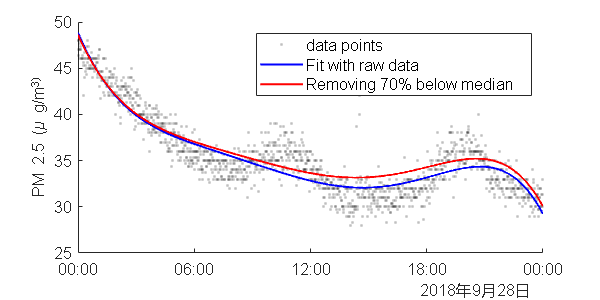

time_num = (datenum(time)-floor(datenum(time)))*24*60*60;
fig = figure('Position', [0,0,600,300]);
h = scatter(time,pm2d5,'.k');
h.MarkerFaceAlpha = .25;
h.MarkerEdgeAlpha = .25;
hold on
%%% insert your code here %%%
% note: this is the plot for (d), make sure that you plot both of the fitted
% curves. Please adjust the linewidth (if necessary) and use different colors
% to differentiate different curves

% hint: MATLAB functions find(), randi(), fix(), polyfit(), polyval() might be helpful
% Fit a 5-degree polynomial to the entire data
p_full = polyfit(time_num, pm2d5, 5);
pm2d5_full_fit = polyval(p_full, time_num);

% Plot the fit for the full data
plot(time, pm2d5_full_fit, 'b', 'LineWidth', 1.5);

% Find the median of the PM2.5 values
median_pm2d5 = median(pm2d5);

% Find the indices of data points below the median
below_median_idx = find(pm2d5 < median_pm2d5);

% Randomly select 70% of these indices to remove
num_to_remove = floor(0.7 * length(below_median_idx));
rand_indices_to_remove = below_median_idx(randperm(length(below_median_idx), num_to_remove));

% Create a reduced dataset by removing the selected indices
pm2d5_reduced = pm2d5;
pm2d5_reduced(rand_indices_to_remove) = [];
time_reduced = time;
time_reduced(rand_indices_to_remove) = [];
time_num_reduced = time_num;
time_num_reduced(rand_indices_to_remove) = [];

% Fit a 5-degree polynomial to the reduced data
p_reduced = polyfit(time_num_reduced, pm2d5_reduced, 5);
pm2d5_reduced_fit = polyval(p_reduced, time_num);

% Plot the fit for the reduced data
plot(time, pm2d5_reduced_fit, 'r', 'LineWidth', 1.5);% Plot the fit for the reduced data






%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
legend('data points','Fit with raw data','Removing 70% below median')
ylabel('PM 2.5 (\mu g/m^3)')
set(findall(gcf,'-property','FontSize'),'FontSize',12)

### (d) Your Answer:

Observe and describe the impact of dataset bias on the fit:

- Shift in Curve: The red curve, representing the fit after removing the lower values, is generally higher than the blue curve, especially noticeable in the time periods where more data points have been removed. This suggests that the model is overestimating PM2.5 values where it lacks data.

- Change in Fit Quality: The fit to the reduced dataset may appear to be smoother due to the removal of lower data points, which could be perceived as less variability in the PM2.5 values. However, this smoothness is misleading because it comes at the expense of losing important variance in the data that the original model (blue curve) could capture.

- Bias Towards Higher Values: By selectively removing data points below the median, the training dataset becomes biased towards higher PM2.5 values. The model is then trained predominantly on these higher values, which biases the fit towards overestimating the PM2.5 concentration across the entire time series.

- Implications for Predictive Accuracy: If the model trained on the biased dataset were to be used for predictive purposes, it would likely predict higher PM2.5 concentrations than would be expected had it been trained on the full dataset. This could have serious implications for decision-making processes that rely on accurate PM2.5 forecasts.

### (e) 

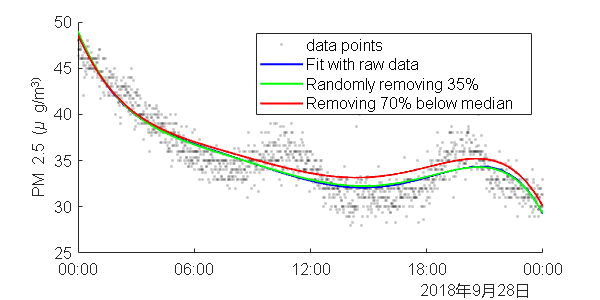

time_num = (datenum(time)-floor(datenum(time)))*24*60*60;
fig = figure('Position', [0,0,600,300]);
h = scatter(time,pm2d5,'.k');
h.MarkerFaceAlpha = .25;
h.MarkerEdgeAlpha = .25;
hold on
%%% insert your code here %%%
% note: this is the plot for (e), make sure that you plot all 3 fitted
% curves. Please adjust the linewidth (if necessary) and use different colors
% to differentiate different curves

% hint: MATLAB functions find(), randi(), fix(), polyfit(), polyval() might be helpful

% First, fit a 5-degree polynomial to the entire data
p_full = polyfit(time_num, pm2d5, 5);
pm2d5_full_fit = polyval(p_full, time_num);

% Plot the fit for the full data
plot(time, pm2d5_full_fit, 'b', 'LineWidth', 1.5);

% Next, randomly remove 35% of the entire data
num_to_remove_entire = floor(0.35 * length(pm2d5));
rand_indices_to_remove_entire = randperm(length(pm2d5), num_to_remove_entire);

% Create a reduced dataset by removing the selected indices
pm2d5_reduced_random = pm2d5;
pm2d5_reduced_random(rand_indices_to_remove_entire) = [];
time_reduced_random = time;
time_reduced_random(rand_indices_to_remove_entire) = [];
time_num_reduced_random = time_num;
time_num_reduced_random(rand_indices_to_remove_entire) = [];

% Fit a 5-degree polynomial to the randomly reduced data
p_reduced_random = polyfit(time_num_reduced_random, pm2d5_reduced_random, 5);
pm2d5_reduced_random_fit = polyval(p_reduced_random, time_num);

% Plot the fit for the randomly reduced data
plot(time, pm2d5_reduced_random_fit, 'g', 'LineWidth', 1.5);

% Now, assuming you already have the reduced dataset from part (d) where you removed 70% below median
% Fit a 5-degree polynomial to the biased reduced data (from part d)
p_reduced_biased = polyfit(time_num_reduced, pm2d5_reduced, 5);
pm2d5_reduced_biased_fit = polyval(p_reduced_biased, time_num);

% Plot the fit for the biased reduced data
plot(time, pm2d5_reduced_biased_fit, 'r', 'LineWidth', 1.5);

% Update the legend to include all three fits
legend('data points', 'Fit with raw data', 'Fit after removing 70% below median', 'Fit after randomly removing 35%');
ylabel('PM 2.5 (\mu g/m^3)');
set(findall(gcf,'-property','FontSize'),'FontSize',12);







%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
legend('data points','Fit with raw data','Randomly removing 35%','Removing 70% below median')
ylabel('PM 2.5 (\mu g/m^3)')
set(findall(gcf,'-property','FontSize'),'FontSize',12)

### (e) Your Answer:

In this figure we can see that randomly removing 35% curve closely follow the blue curve that fitting with raw data. The red curve in (d) deviates slightly from the blue curve, particularly in the latter part of the time series, which suggests that removing data based on value can introduce bias into the model. Therefore, the polynomial regression fit on a randomly reduced dataset (green curve) is more representative of the full dataset than the fit on a dataset reduced with bias (red curve). The green curve indicates that a random reduction of the dataset size does not significantly alter the underlying trend captured by the model, while the red curve demonstrates how selective data removal can lead to biased predictions. This underlines the importance of data representativeness in statistical modeling to ensure the reliability of the model's predictions.

### (f) Your Answer:

Biased datasets can significantly influence regression fits and the conclusions drawn from them:

- Distorted Model Parameters: Bias in a dataset leads to regression models that have coefficients (parameters) which do not accurately represent the true relationships within the population. For instance, if higher values are overrepresented in the data, the regression might suggest stronger relationships than actually exist.

- Misleading Predictions: A model trained on a biased dataset will produce predictions that are systematically skewed. This could be particularly problematic for decision-making processes that rely on accurate forecasts.

- Underestimation or Overestimation: If a dataset has been biased by the exclusion of a certain range of values, the regression fit will either underestimate or overestimate the dependent variable in the range of excluded data. In the example of PM2.5 data, removing lower values could lead to overestimation of pollution levels.

- Poor Generalizability: A model fitted on a biased dataset will likely perform poorly when making predictions on new, unbiased data because the model has learned the bias as if it were a true underlying pattern.

Strategies:

- Comprehensive Data Collection: Ensure the data collection process is as inclusive as possible to gather a dataset that accurately reflects the population or phenomenon of interest.

- Random Sampling: Use random sampling methods when collecting data to minimize selection bias. This means every member of the population has an equal chance of being included in the sample.

- Stratified Sampling: If certain subgroups are known to be underrepresented, stratified sampling can ensure that all segments of the population are included proportionally in the sample.

- Post-Stratification: Adjust the weight of certain observations in the analysis phase to better reflect their true proportion in the population.

- Missing Data Techniques: Employ techniques to handle missing data, such as imputation, rather than simply excluding missing values which can introduce bias.

- Sensitivity Analysis: Perform sensitivity analyses to understand how different levels of bias affect the model's outputs. This can help in understanding the robustness of the model's predictions.

- Regularization Techniques: Use regularization methods in regression (like Lasso or Ridge) that can reduce overfitting to biased samples by penalizing large coefficients.

- Model Validation: Validate the model using a different dataset that is known to be unbiased, or cross-validate using different subsets of the data to ensure the model's predictions hold up under varying conditions.

## Part II

### (a)

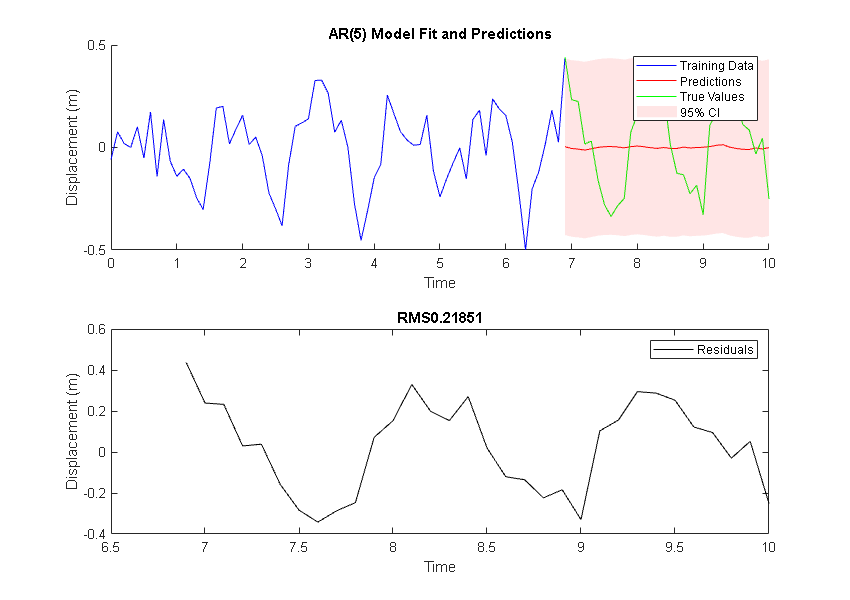

clear
clc
load hw4_2_1.mat
time = displacement(:,1);
y = displacement(:,2);

fig = figure('Position',[0,0,850,600]);

subplot(2,1,1)
%%% insert your code here %%%
% note: this is the first subplot for model fitting
% Define the number of data points for training
n_train = 70;
n_test = 30; % Last 30 measurements for testing

% Fit an AR(5) model to the first 70 measurements
train_data = y(1:n_train);
model_ar5 = ar(train_data, 5);

% because 'forecast' is for multi-step ahead forecasting in a System Identification context
y_pred = predict(model_ar5, y, n_test);

% The predicted values are aligned with the end of the training data
% So, we need to take the last 'n_test' values
y_pred = y_pred(n_train:end);

% Calculate residuals
residuals = y(n_train:end) - y_pred;



% Calculate 95% confidence interval for the predictions
pred_std = std(residuals);
conf_interval = 1.96 * pred_std;

% Plot the training data, predictions, and true values
hold on;
plot(time(1:n_train), train_data, 'b', 'DisplayName', 'Training Data');
plot(time(n_train:end), y_pred, 'r', 'DisplayName', 'Predictions');
plot(time(n_train:end), y(n_train:end), 'g', 'DisplayName', 'True Values');
patch([time(n_train:end); flipud(time(n_train:end))], ...
      [y_pred-conf_interval; flipud(y_pred+conf_interval)], ...
      'r', 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', '95% CI');
hold off;
legend show;
xlabel('Time');
ylabel('Displacement (m)');
title('AR(5) Model Fit and Predictions');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

subplot(2,1,2)
%%% insert your code here %%%
% note: this is the second subplot for the residual
plot(time(n_train:end), residuals, 'k', 'DisplayName', 'Residuals');
legend show;
xlabel('Time');
ylabel('Residuals (m)');
title('Residuals of AR(5) Model Predictions');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
title(['RMS',num2str(rms(residuals))])
xlabel('Time')
ylabel('Displacement (m)')

### (b)

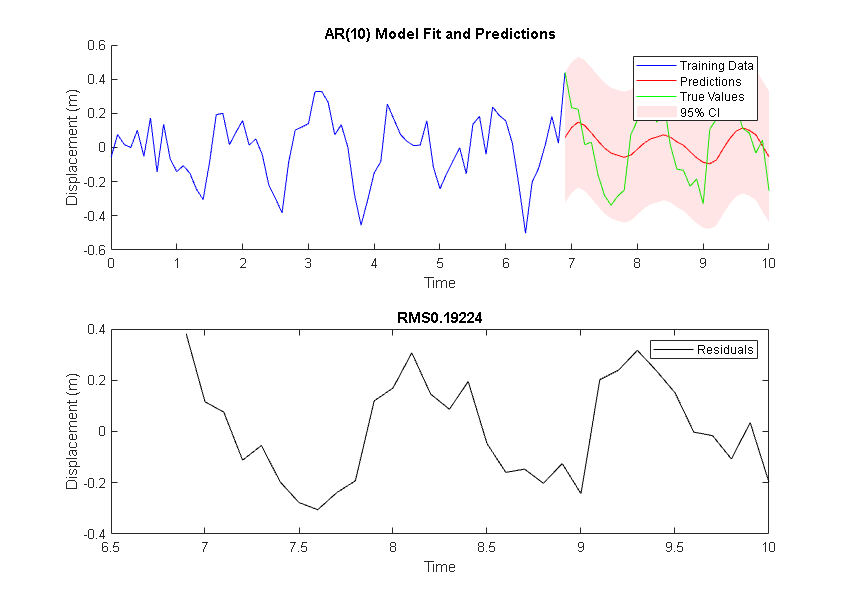

fig = figure('Position',[0,0,850,600]);

subplot(2,1,1)
%%% insert your code here %%%
% note: this is the first subplot for model fitting
% Define the number of data points for training
n_train = 70;
n_test = 30; % Last 30 measurements for testing

% Fit an AR(10) model to the first 70 measurements
train_data = y(1:n_train);
model_ar10 = ar(train_data, 10);

% because 'forecast' is for multi-step ahead forecasting in a System Identification context
y_pred = predict(model_ar10, y, n_test);

% The predicted values are aligned with the end of the training data
% So, we need to take the last 'n_test' values
y_pred = y_pred(n_train:end);

% Calculate residuals
residuals = y(n_train:end) - y_pred;

% Calculate 95% confidence interval for the predictions
pred_std = std(residuals);
conf_interval = 1.96 * pred_std;

% Plot the training data, predictions, and true values
hold on;
plot(time(1:n_train), train_data, 'b', 'DisplayName', 'Training Data');
plot(time(n_train:end), y_pred, 'r', 'DisplayName', 'Predictions');
plot(time(n_train:end), y(n_train:end), 'g', 'DisplayName', 'True Values');
patch([time(n_train:end); flipud(time(n_train:end))], ...
      [y_pred-conf_interval; flipud(y_pred+conf_interval)], ...
      'r', 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', '95% CI');
hold off;
legend show;
xlabel('Time');
ylabel('Displacement (m)');
title('AR(10) Model Fit and Predictions');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

subplot(2,1,2)
%%% insert your code here %%%
% note: this is the second subplot for the residual
plot(time(n_train:end), residuals, 'k', 'DisplayName', 'Residuals');
legend show;
xlabel('Time');
ylabel('Residuals (m)');
title('Residuals of AR(10) Model Predictions');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
title(['RMS',num2str(rms(residuals))])
xlabel('Time')
ylabel('Displacement (m)')

### Your Answer:

### c) 

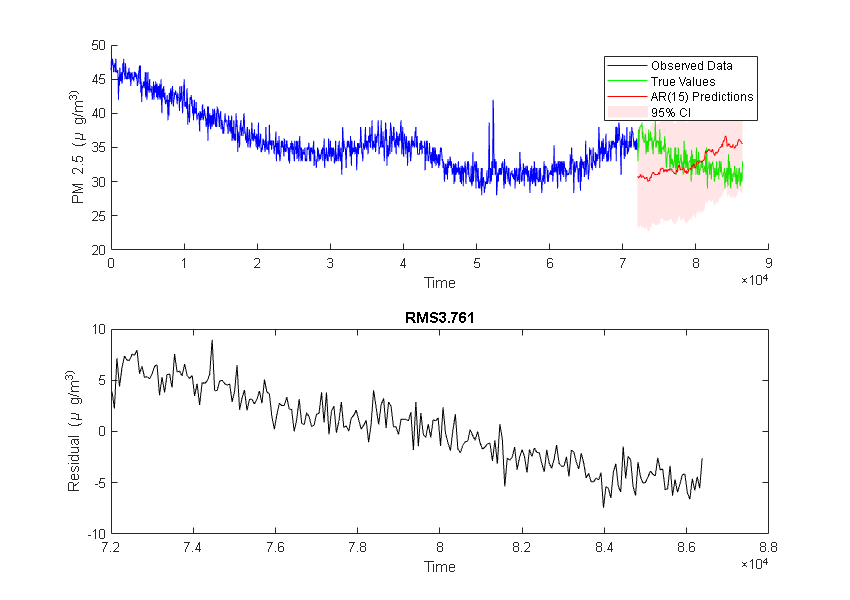

clear
clc
city_name = 'Foshan';

load hw4_2_2.mat
pm2d5 = data.pm2d5;
time = data.time;
warning ('off','all');
time_num = (datenum(time)-floor(datenum(time)))*24*60*60;
X = time_num;

fig = figure('Position',[0,0,850,600]);

subplot(2,1,1)
%%% insert your code here %%%
% note: this subplot is for AR(15) model fitting
% Training and test data separation
train_hours = 20; % first 20-hour measurements
test_hours = 4; % last 4-hour measurements
n_train = train_hours * 60; % convert hours to minutes
n_test = test_hours * 60; % convert hours to minutes

% Fit AR(15) model
data_train = pm2d5(1:n_train);
model_ar15 = ar(data_train, 15);

% Predict the last 4 hours
y_pred_ar15 = predict(model_ar15, pm2d5, n_test);

% Extract the last 4 hours of predictions
y_pred_ar15 = y_pred_ar15(n_train:end);

% Calculate 95% confidence interval for the predictions
residual_ar15 = pm2d5(n_train:end) - y_pred_ar15;
pred_std = std(residual_ar15);
conf_interval = 1.96 * pred_std;


hold on;
plot(time_num(1:n_train), data_train, 'b', 'DisplayName', 'Observed Data');
plot(time_num(n_train:end), pm2d5(n_train:end), 'g', 'DisplayName', 'True Values');
plot(time_num(n_train:end), y_pred_ar15, 'r', 'DisplayName', 'AR(15) Predictions');
patch([time_num(n_train:end); flipud(time_num(n_train:end))], ...
      [y_pred_ar15-conf_interval; flipud(y_pred_ar15+conf_interval)], ...
      'r', 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', '95% CI');
hold off;

legend show;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
xlabel('Time')
ylabel('PM 2.5 (\mu g/m^3)')
  
subplot(2,1,2)
%%% insert your code here %%%
% note: this subplot is for AR(15) residual
% Calculate residuals for AR(15)

plot(time_num(n_train:end), residual_ar15, 'k', 'DisplayName', 'Residuals');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
title(['RMS',num2str(rms(residual_ar15))])
xlabel('Time')
ylabel('Residual (\mu g/m^3)')

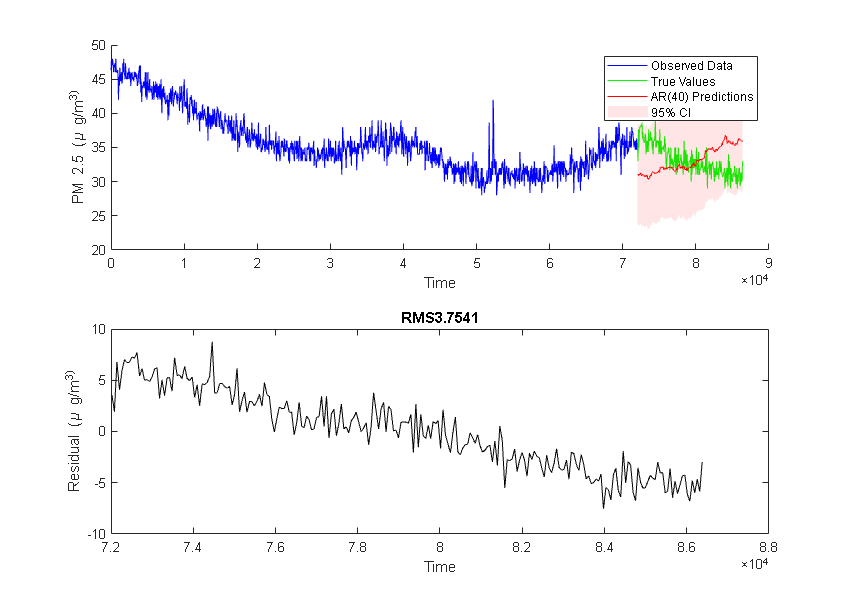


fig = figure('Position',[0,0,850,600]);

subplot(2,1,1)
%%% insert your code here %%%
% note: this subplot is for AR(40) model fitting
% note: this subplot is for AR(15) model fitting
% Training and test data separation
train_hours = 20; % first 20-hour measurements
test_hours = 4; % last 4-hour measurements
n_train = train_hours * 60; % convert hours to minutes
n_test = test_hours * 60; % convert hours to minutes

% Fit AR(15) model
data_train = pm2d5(1:n_train);
model_ar40 = ar(data_train, 40);

% Predict the last 4 hours
y_pred_ar40 = predict(model_ar40, pm2d5, n_test);

% Extract the last 4 hours of predictions
y_pred_ar40 = y_pred_ar40(n_train:end);

% Calculate 95% confidence interval for the predictions
residual_ar40 = pm2d5(n_train:end) - y_pred_ar40;
pred_std = std(residual_ar40);
conf_interval = 1.96 * pred_std;


hold on;
plot(time_num(1:n_train), data_train, 'b', 'DisplayName', 'Observed Data');
plot(time_num(n_train:end), pm2d5(n_train:end), 'g', 'DisplayName', 'True Values');
plot(time_num(n_train:end), y_pred_ar40, 'r', 'DisplayName', 'AR(40) Predictions');
patch([time_num(n_train:end); flipud(time_num(n_train:end))], ...
      [y_pred_ar40-conf_interval; flipud(y_pred_ar40+conf_interval)], ...
      'r', 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', '95% CI');
hold off;

legend show;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
xlabel('Time')
ylabel('PM 2.5 (\mu g/m^3)')
  
subplot(2,1,2)
%%% insert your code here %%%
% note: this subplot is for AR(40) residual
plot(time_num(n_train:end), residual_ar40, 'k', 'DisplayName', 'Residuals');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
title(['RMS',num2str(rms(residual_ar40))])
xlabel('Time')
ylabel('Residual (\mu g/m^3)')

### Your Answer:

## Part III

close all
clear
clc

load hw4_3.mat
pm2d5= data.pm2d5;
time = data.time;
time_num = (datenum(time)-floor(datenum(time)))*24*60*60;
lat = data.lat;
lon = data.lon;

% normalize the spatial and temporal data
x = [normalize(time_num,'range'),normalize(lat,'range'),normalize(lon,'range')];
y = pm2d5;

### (a)

clearvars x_train y_train x_test y_test gprMdl y_pred
%%% insert your code here %%%
% Number of folds for cross-validation
k = 5;

% Setup for cross-validation
cv = cvpartition(length(y), 'KFold', k);

% Array to store RMSE for each fold
rmse_values = zeros(k, 1);

% Loop over each fold
for i = 1:k
    % Training and test indices
    trainIdx = cv.training(i);
    testIdx = cv.test(i);

    % Training and test data
    x_train = x(trainIdx, :);
    y_train = y(trainIdx);
    x_test = x(testIdx, :);
    y_test = y(testIdx);

    % Train GPR model
    gprMdl = fitrgp(x_train, y_train, 'KernelFunction', 'exponential');

    % Predict on test data
    y_pred = predict(gprMdl, x_test);

    % Calculate and store RMSE for this fold
    rmse_values(i) = sqrt(mean((y_pred - y_test).^2));
end

% Calculate average RMSE
average_rmse = mean(rmse_values);

% Display the average RMSE
disp(['Average RMSE: ', num2str(average_rmse)]);

Average RMSE: 8.9092






%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### (b)

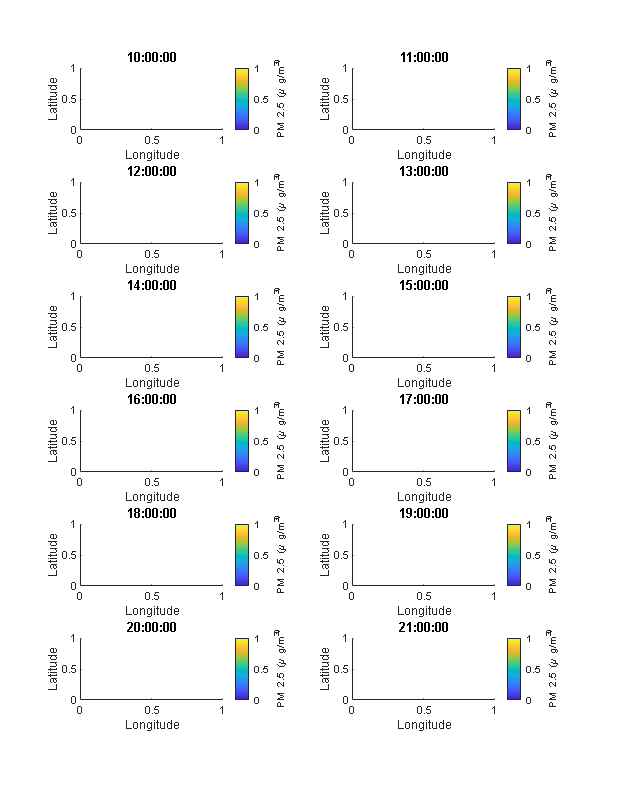

fig = figure('Position', [0,0,850,1100]);
for i = 1:12
    time_ = (i+9)/24;
    
    subplot(6,2,i)
     %%% insert your code here %%%
     % hint: MATLAB function meshgrid(), surf() might be helpful

     
     
     
     
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    shading interp    
    view(0,90)
    xlabel('Longitude')
    ylabel('Latitude')
    c = colorbar;
    ylabel(c,'PM 2.5 (\mu g/m^3)')        
    title(datestr(time_,'HH:MM:SS'),'fontsize',10)
end

### (b) Your Answer:

### (c)

clearvars x_train y_train x_test y_test gprMdl y_pred
%%% insert your code here %%%
% note: this section is for you to compute the GPR model and report RMSE like (a)



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


fig = figure('Position', [0,0,850,1100]);
for i = 1:12
    time_ = (i+9)/24;
    subplot(6,2,i);
     %%% insert your code here %%%
     % hint: MATLAB function meshgrid(), surf() might be helpful

     
     
     
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    shading interp    
    view(0,90)
    xlabel('Longitude')
    ylabel('Latitude')
    c = colorbar;
    ylabel(c,'PM 2.5 (\mu g/m^3)')        
    title(datestr(time_,'HH:MM:SS'),'fontsize',10)
end

### (c) Your Answer:

### (d)

clearvars x_train y_train x_test y_test gprMdl y_pred

%%% insert your code here %%%
% note: this section is for you to compute the GPR model and report RMSE like (a)




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

fig = figure('Position', [0,0,850,1100]);
for i = 1:12
    time_ = (i+9)/24;
    subplot(6,2,i);
     %%% insert your code here %%%
     % hint: MATLAB function meshgrid(), surf() might be helpful

     
     
     
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    shading interp    
    view(0,90)
    xlabel('Longitude')
    ylabel('Latitude')
    c = colorbar;
    ylabel(c,'PM 2.5 (\mu g/m^3)')        
    title(datestr(time_,'HH:MM:SS'),'fontsize',10)
end

### (d) Your Answer:

### (e) Your Answer: 